% green = "images/green_cubes_Color.png";

green = "images/25_Color.png"

green = "images/25_Color.png"

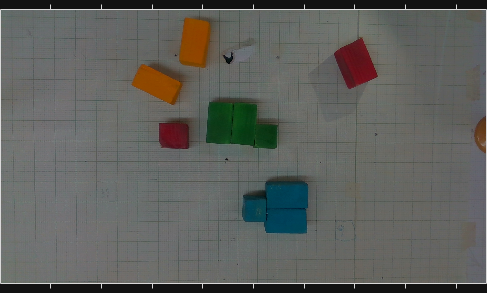

% green = "images/24_Color.png"



[I_g, g_map] = imread(green); % TODO: Adaptive hist equalization
imshow(I_g)

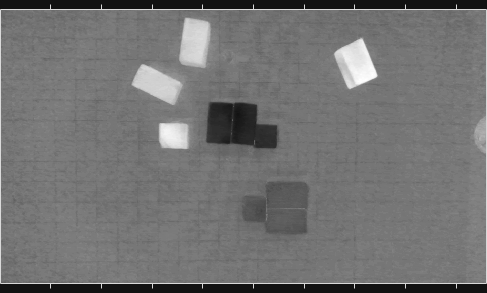

[rg,gg,bg] = imsplit(I_g);
imgLab = rgb2lab(I_g);
[L,a,b] = imsplit(imgLab);
imshow(a,[])

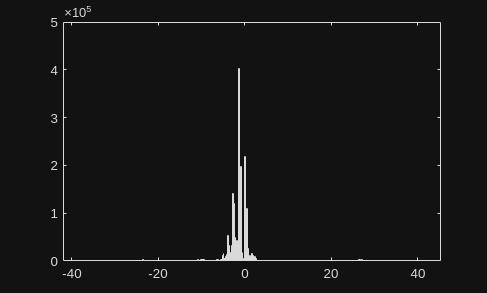

histogram(a)

SE = strel("cube", 1);
a_eroded = imclose(a, SE);
imshow(a_eroded, []);

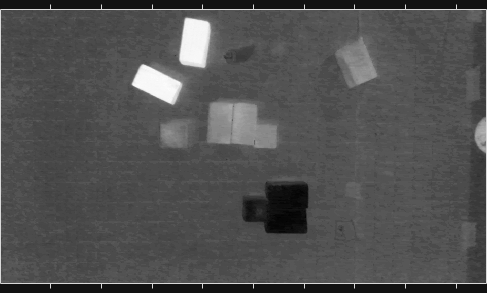

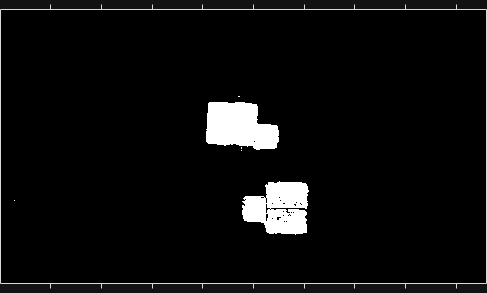

masked = a_eroded < -8;

imshow(masked);

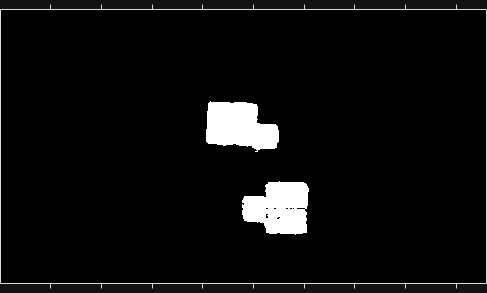

% Segmentation stage
masked_med = wiener2(masked_eroded, [2,2]);
mask1 = bwareaopen(masked_med, 100);
imshow(mask1)


% gmask = imbinarize(g)
% imshow(gmask)

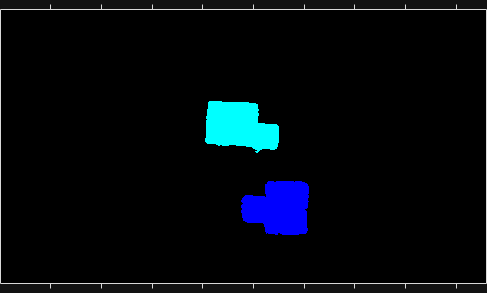

% 

boxCC = bwconncomp(mask4);
boxLabel = labelmatrix(boxCC);
boxRGB = label2rgb(boxLabel, "jet", "k", "shuffle");
imshow(boxRGB);

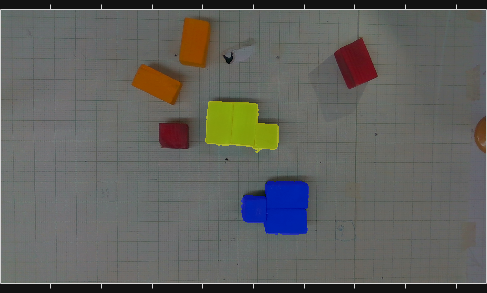


overlay = labeloverlay(I_g, boxLabel, 'Transparency', 0.5);
imshow(overlay)

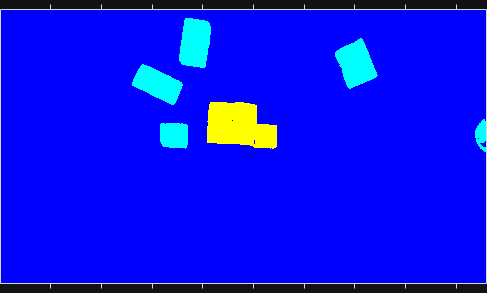

clusters = segment_cluster(I_g, 3);
imshow(label2rgb(clusters))

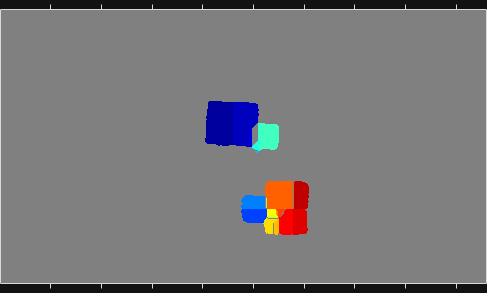

Icomp = -bwdist(~mask1);
L = watershed(Icomp);
L(~mask4) = 0;
rgb = label2rgb(L,'jet',[.5 .5 .5]);
imshow(rgb, []);

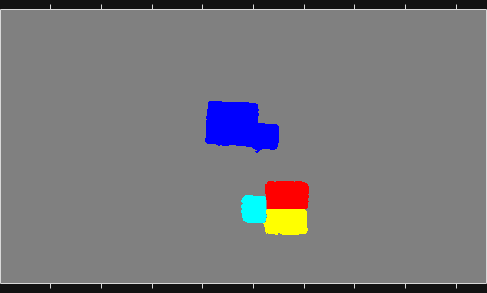

Icomp = -bwdist(~mask1);
Ifilt = imhmin(Icomp,10);
L = watershed(Ifilt);
L(~mask4) = 0;

rgb = label2rgb(L,'jet',[.5 .5 .5]);
imshow(rgb, []);